% SET OPTIONS
KneipA_on = false;
KneipN_on =true;
KneipO_on = false;
Grunert_on = false;
MatlabPnP_on = false;
importLogs = true;

% INITIALISE CONSTANTS

%K = [1274.58238813250 0 627.693937913345; 0 1273.36371905619 405.441250468717; 0 0 1]; %23 mm calibration
%K=   [605.8071 0 316.6903; 0 608.4646 256.6409; 0 0 1.0000]; %31 mm calib
K = [1109 0 640; 0 1109 360; 0 0 1]; %virtual camera
checkerSize = [5 8];
checkerEdgeLength = 31; %mm

%Known coordinate transformations (mapping)
Rt_board2W = [1 0 0 0; 0 -1 0 0; 0 0 -1 0];
R_unreal2World = [-1 0 0; 0 -1 0; 0 0 1];

%INITIALISE WORLD MAP
X_pnts_W = p3pFuncs.calcCheckerEdgeCoords_W(checkerSize, checkerEdgeLength, Rt_board2W)

X_pnts_W =      0     0     0     0    31    31    31    31    62    62    62    62    93    93    93    93   124   124   124   124   155   155   155   155   186   186   186   186
     0   -31   -62   -93     0   -31   -62   -93     0   -31   -62   -93     0   -31   -62   -93     0   -31   -62   -93     0   -31   -62   -93     0   -31   -62   -93
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


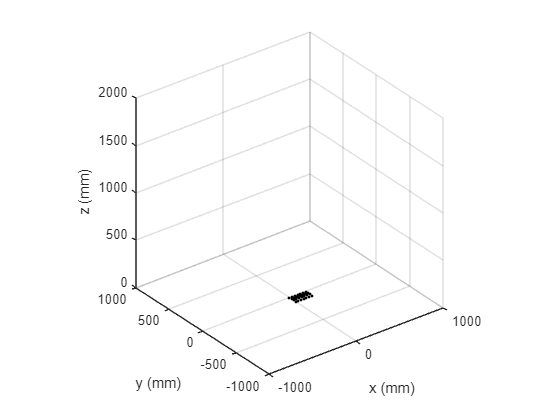

%INTIALISE PLOT
close all
trajFig = figure();
worldAx = p3pPlotting.initPlot(trajFig, [-1000,1000], [-1000,1000], [0 2000]);
p3pPlotting.addCheckerboard(worldAx, X_pnts_W);

%ADD TRAJECTORIES
if KneipA_on == true
    [lineObj_KneipA_1, axTextArr_KneipA_1, axLineArr_KneipA_1] = p3pPlotting.addTraj(worldAx, 'Kneip (Alyssa) 1', '-or', '-r');
    [lineObj_KneipA_2, axTextArr_KneipA_2, axLineArr_KneipA_2] = p3pPlotting.addTraj(worldAx, 'Kneip (Alyssa) 2', '-ob', '-b');
    [lineObj_KneipA_3, axTextArr_KneipA_3, axLineArr_KneipA_3] = p3pPlotting.addTraj(worldAx, 'Kneip (Alyssa) 3', '-om', '-m');
    [lineObj_KneipA_4, axTextArr_KneipA_4, axLineArr_KneipA_4] = p3pPlotting.addTraj(worldAx, 'Kneip (Alyssa) 4', '-oc', '-c');
    
end
if KneipN_on ==true
    [lineObj_KneipN_1, axTextArr_KneipN_1, axLineArr_KneipN_1] = p3pPlotting.addTraj(worldAx, 'Kneip (Nagano) 1', '-or', '-r');
    [lineObj_KneipN_2, axTextArr_KneipN_2, axLineArr_KneipN_2] = p3pPlotting.addTraj(worldAx, 'Kneip (Nagano) 2', '-ob', '-b');
    [lineObj_KneipN_3, axTextArr_KneipN_3, axLineArr_KneipN_3] = p3pPlotting.addTraj(worldAx, 'Kneip (Nagano) 3', '-om', '-m');
    [lineObj_KneipN_4, axTextArr_KneipN_4, axLineArr_KneipN_4] = p3pPlotting.addTraj(worldAx, 'Kneip (Nagano) 4', '-oc', '-c');

end
if KneipO_on ==true
    [lineObj_KneipO, axTextArr_KneipO, axLineArr_KneipO] = p3pPlotting.addTraj(worldAx, 'Kneip (Original)', '-ok', '-k');
end
if MatlabPnP_on == true
    [lineObj_Mat, axTextArr_Mat, axLineArr_Mat] = p3pPlotting.addTraj(worldAx, 'Matlab P3P', '-ob', '-b');
end
if Grunert_on ==true
    [lineObj_Grun, axTextArr_Grun, axLineArr_Grun] = p3pPlotting.addTraj(worldAx, 'Grunert', '-oc', '-c');
end
if importLogs == true
    [lineObj_Ver, axTextArr_Ver, axLineArr_Ver] = p3pPlotting.addTraj(worldAx, 'Logged', '-og', '-g');
end

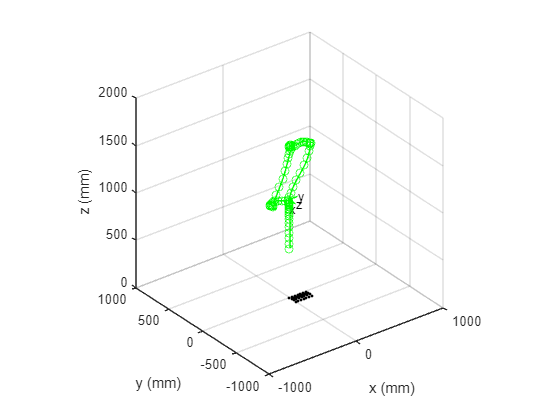

%IMPORT & PLOT LOGGED DATA
if importLogs ==true
    rtHist_Ver = imgFuncs.importSimLog("C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\camPose.mat",  R_unreal2World);
    p3pPlotting.updateTraj(lineObj_Ver, axTextArr_Ver, axLineArr_Ver, rtHist_Ver);
end

%IMPORT IMAGES
%imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Few\Left";
% imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Few";
%imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Few\Up-right";
imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Few\Problem";
%imgFolder = "C:\Users\alyss\OneDrive - University of Cape Town\Sandbox\PnP\Verification\Few\Down";


I_seq = zeros(1,1,1);
I_seq = imgFuncs.importImageSeq(imgFolder);

%INITIALISE RT HISTORIES
if KneipA_on == true
    rtHist_KneipA_1 = zeros(3,4,1);
    rtHist_KneipA_2 = zeros(3,4,1);
    rtHist_KneipA_3 = zeros(3,4,1);
    rtHist_KneipA_4 = zeros(3,4,1);
end
if KneipN_on ==true
    rtHist_KneipN_1 = zeros(3,4,1);
    rtHist_KneipN_2 = zeros(3,4,1);
    rtHist_KneipN_3 = zeros(3,4,1);
    rtHist_KneipN_4 = zeros(3,4,1);
end
if KneipO_on ==true
    rtHist_KneipO_1 = zeros(3,4,1);    
    rtHist_KneipO_2 = zeros(3,4,1);
    rtHist_KneipO_3 = zeros(3,4,1);
    rtHist_KneipO_4 = zeros(3,4,1);
end
if MatlabPnP_on == true
    rtHist_Mat = zeros(3,4,1);
end
if Grunert_on ==true
    rtHist_Grun_1 = zeros(3,4,1);
    rtHist_Grun_2 = zeros(3,4,1);
    rtHist_Grun_3 = zeros(3,4,1);
    rtHist_Grun_4 = zeros(3,4,1);
end

Working on frame 1
Working on frame 2


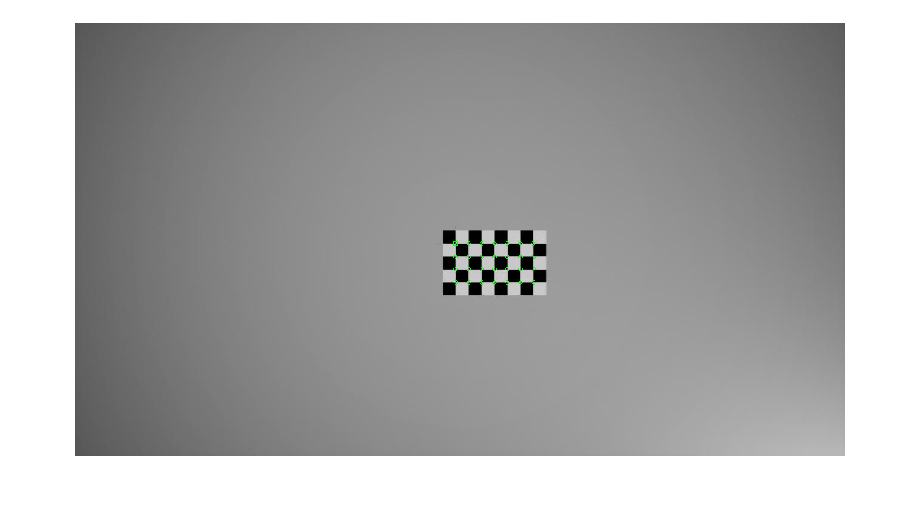

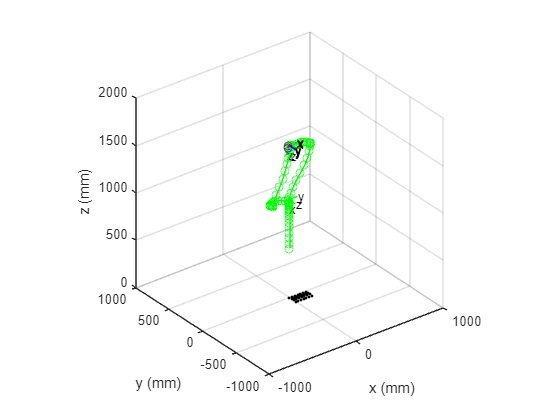

%RUN AND PLOT P3P FOR EACH CHECKERBOARD IMAGE
goodFrameCounter = 0;
for i=1:size(I_seq,3)

    disp(strcat("Working on frame ", string(i)));
    
    %Get current frame
    I=I_seq(:,:,i);
    imageArrSize = size(I);
    imageSize=imageArrSize(1:2);

    %Find checkerboard corners
    [x_pnts_i, checkerSize_detected] = detectCheckerboardPoints(I);
    x_pnts_i = transpose(x_pnts_i);
    %x_pnts_i = round(x_pnts_i);

    %Display checkerboard
    if i==1
        checkerFig = figure();
        checkerAx = axes('Parent', checkerFig);
        checkerImg = imshow(imgFuncs.markDetectedCheckers(I, x_pnts_i), 'Parent', checkerAx);
    else
        checkerImg.CData = (imgFuncs.markDetectedCheckers(I, x_pnts_i));
        drawnow;
    end 
    

    %discard any frames where too few corners have been detected
    if checkerSize_detected ~= checkerSize
        continue
    end

    %otherwise, run P3P
    goodFrameCounter = goodFrameCounter +1;
    rtArrCW = zeros(3,4,1);
    rtArrWC = zeros(3,4,1);
    if KneipO_on == true
        Rt = p3pRun.KneipO(x_pnts_i, X_pnts_W, K, checkerSize);
        rtHist_KneipO(:,:,goodFrameCounter) = Rt;
        p3pPlotting.updateTraj(lineObj_KneipO, axTextArr_KneipO, axLineArr_KneipO, rtHist_KneipO);
    end
    if KneipA_on == true
        [Rt, err, rtArrCW, rtArrWC] = p3pRun.KneipA(x_pnts_i, X_pnts_W, K, checkerSize);
        rtHist_KneipA_1(:,:,goodFrameCounter) = rtArrCW(:,:,1);
        rtHist_KneipA_2(:,:,goodFrameCounter) = rtArrCW(:,:,2);
        rtHist_KneipA_3(:,:,goodFrameCounter) = rtArrCW(:,:,3);
        rtHist_KneipA_4(:,:,goodFrameCounter) = rtArrCW(:,:,4);
        p3pPlotting.updateTraj(lineObj_KneipA_1, axTextArr_KneipA_1, axLineArr_KneipA_1, rtHist_KneipA_1);
        p3pPlotting.updateTraj(lineObj_KneipA_2, axTextArr_KneipA_2, axLineArr_KneipA_2, rtHist_KneipA_2);
        p3pPlotting.updateTraj(lineObj_KneipA_3, axTextArr_KneipA_3, axLineArr_KneipA_3, rtHist_KneipA_3);
        p3pPlotting.updateTraj(lineObj_KneipA_4, axTextArr_KneipA_4, axLineArr_KneipA_4, rtHist_KneipA_4);
    end

    if KneipN_on == true
        [Rt, err, rtArrCW, rtArrWC] = p3pRun.KneipN(x_pnts_i, X_pnts_W, K, checkerSize);
        rtHist_KneipN_1(:,:,goodFrameCounter) = rtArrWC(:,:,1);
        rtHist_KneipN_2(:,:,goodFrameCounter) = rtArrWC(:,:,2);
        rtHist_KneipN_3(:,:,goodFrameCounter) = rtArrWC(:,:,3);
        rtHist_KneipN_4(:,:,goodFrameCounter) = rtArrWC(:,:,4);
        p3pPlotting.updateTraj(lineObj_KneipN_1, axTextArr_KneipN_1, axLineArr_KneipN_1, rtHist_KneipN_1);
        p3pPlotting.updateTraj(lineObj_KneipN_2, axTextArr_KneipN_2, axLineArr_KneipN_2, rtHist_KneipN_2);
        p3pPlotting.updateTraj(lineObj_KneipN_3, axTextArr_KneipN_3, axLineArr_KneipN_3, rtHist_KneipN_3);
        p3pPlotting.updateTraj(lineObj_KneipN_4, axTextArr_KneipN_4, axLineArr_KneipN_4, rtHist_KneipN_4);

    end

    if MatlabPnP_on == true
        Rt = p3pRun.MatlabPnP(K,x_pnts_i, X_pnts_W, imageSize, 0.1);
        rtHist_Mat(:,:,goodFrameCounter) = Rt;
        p3pPlotting.updateTraj(lineObj_Mat, axTextArr_Mat, axLineArr_Mat, rtHist_Mat);
    end

    if Grunert_on == true
        Rt = p3pRun.Grunert(x_pnts_i, X_pnts_W, K, checkerSize);
        rtHist_Grun(:,:,goodFrameCounter) = Rt;
        p3pPlotting.updateTraj(lineObj_Grun, axTextArr_Grun, axLineArr_Grun, rtHist_Grun);
    end
end